strike = 1.1

strike = 1.1000

valueDate = datetime(2008,02,15)

valueDate = datetime
   15-Feb-2008


timeToMaturity = 1/3

timeToMaturity = 0.3333

volatility = 0.212

volatility = 0.2120

discountRate = 0.025 

discountRate = 0.0250

dividendYield = 0.02

dividendYield = 0.0200

nominal = 1e6

nominal = 1000000

underlyingPrice = 1

underlyingPrice = 1

blkprice: 

forwardPrice = underlyingPrice * exp((discountRate - dividendYield) * timeToMaturity);
analyticOptionOnForwardPrice = blkprice(forwardPrice,strike,discountRate,timeToMaturity,volatility)

analyticOptionOnForwardPrice = 0.0163

CRR Tree Approach Notice when number of timesteps is 10, we get a very accurate model because we are lucky, precision must be sawtooth function of some sorts. Run this with 11 timesteps, it will be worse than with 10, but as N increases the errors dampen. 

numberOfTimesteps = 2e3

numberOfTimesteps = 2000

timestepSize = timeToMaturity / numberOfTimesteps;
yieldAdjustedDiscountRate = discountRate - dividendYield

yieldAdjustedDiscountRate = 0.0050

forwardPrice = underlyingPrice * exp((discountRate - dividendYield) * timeToMaturity);
dx = volatility * sqrt(timestepSize);
u = exp(dx);
d = 1/u;

yieldAdjustedGrowthFactorAtTimeStep = 1

yieldAdjustedGrowthFactorAtTimeStep = 1

riskNeutralProbabilityUpCRR = (yieldAdjustedGrowthFactorAtTimeStep - d) / (u - d);

numberOfUpMovements = (0:numberOfTimesteps)';
numberOfDownMovements = numberOfTimesteps - numberOfUpMovements;
netMovements = numberOfUpMovements - numberOfDownMovements;

forwardPriceAtMaturity = exp(log(forwardPrice) + netMovements * dx);

binomialRiskNeutralProbabilities = binopdf(numberOfUpMovements, numberOfTimesteps, riskNeutralProbabilityUpCRR);
optionPayoffs = max(forwardPriceAtMaturity - strike, 0);

expectedPayoffs = binomialRiskNeutralProbabilities .* optionPayoffs;

crrOptionOnforwardPrice = exp(-discountRate * timeToMaturity) * sum(expectedPayoffs)

crrOptionOnforwardPrice = 0.0163

Monte Carlo Approach I think 1e8 

numberOfPaths = 1e6; 
forwardPrice = underlyingPrice * exp((discountRate - dividendYield) * timeToMaturity);
epsilon = randn(numberOfPaths, 1);
unitForwardPriceAtMaturityPaths = (volatility * sqrt(timeToMaturity) * epsilon) - ...
                      (0.5 * volatility^2 * timeToMaturity);

forwardPriceAtMaturity = forwardPrice * exp(unitForwardPriceAtMaturityPaths);

optionPayoffs = max(forwardPriceAtMaturity - strike, 0);

expectedFuturePayoff = mean(optionPayoffs);

monteCarloOptionOnForwardPrice = exp(-discountRate * timeToMaturity) * expectedFuturePayoff

monteCarloOptionOnForwardPrice = 0.0162

Log log ( notice after M > 1e6, we have a problem due to numerical stability I think (because of the probabilities getting really small after so many steps) 

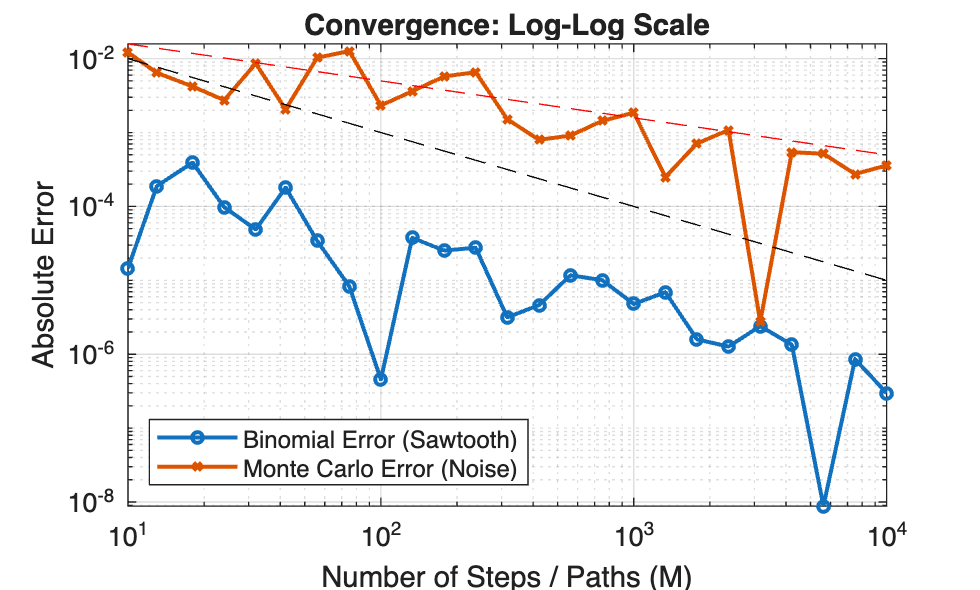

% --- Parameters ---
strike = 1.1;
timeToMaturity = 1/3;
volatility = 0.212;
discountRate = 0.025; 
dividendYield = 0.02;
underlyingPrice = 1;

% Analytical Black-76 Price (The "True" Target)
F = underlyingPrice * exp((discountRate - dividendYield) * timeToMaturity);
d1 = (log(F/strike) + (0.5 * volatility^2) * timeToMaturity) / (volatility * sqrt(timeToMaturity));
d2 = d1 - volatility * sqrt(timeToMaturity);
exactPrice = exp(-discountRate * timeToMaturity) * (F * normcdf(d1) - strike * normcdf(d2));

% Ranges for M (using powers of 10 to see the log-log trend)
M_range = round(logspace(1, 4, 25)); % 10 to 10,000
binomErrors = zeros(size(M_range));
mcErrors = zeros(size(M_range));

for i = 1:length(M_range)
    M = M_range(i);
    
    % --- Binomial Calculation ---
    dt = timeToMaturity / M;
    dx = volatility * sqrt(dt);
    u = exp(dx); d = 1/u;
    p = (1 - d) / (u - d);
    upMoves = (0:M)';
    ST = F * exp((2*upMoves - M) * dx);
    binomPrice = exp(-discountRate * timeToMaturity) * sum(binopdf(upMoves, M, p) .* max(ST - strike, 0));
    binomErrors(i) = abs(binomPrice - exactPrice);
    
    % --- Monte Carlo Calculation ---
    % We use M paths to show how much worse MC is for the same 'M'
    shocks = randn(M, 1);
    fT = F * exp(-0.5 * volatility^2 * timeToMaturity + volatility * sqrt(timeToMaturity) * shocks);
    mcPrice = exp(-discountRate * timeToMaturity) * mean(max(fT - strike, 0));
    mcErrors(i) = abs(mcPrice - exactPrice);
end

% --- Log-Log Plotting ---
figure('Color', 'w');
loglog(M_range, binomErrors, '-o', 'LineWidth', 1.5, 'MarkerSize', 4);
hold on;
loglog(M_range, mcErrors, '-x', 'LineWidth', 1.5, 'MarkerSize', 4);

% Add reference slopes
% Binomial ~ 1/M (Slope -1) | MC ~ 1/sqrt(M) (Slope -0.5)
loglog(M_range, 0.1./M_range, '--k', 'HandleVisibility', 'off'); 
loglog(M_range, 0.05./sqrt(M_range), '--r', 'HandleVisibility', 'off');

grid on;
xlabel('Number of Steps / Paths (M)');
ylabel('Absolute Error');
title('Convergence: Log-Log Scale');
legend('Binomial Error (Sawtooth)', 'Monte Carlo Error (Noise)', 'Location', 'southwest');